% AOCS multi-case asteroid proximity orbit hydrazine model
%
% This script applies the same proximity-orbit wheel desaturation logic to:
%   Partenope_A.mat
%   Parthenope_B.mat
%   Psyche_A_Rsc_theta.mat
%   Psyche_B_Rsc_theta.mat
%   Psyche_C_Rsc_theta.mat
%   Themis_A_Rsc_theta.mat
%   Themis_B_Rsc_theta.mat
%   Themis_C_Rsc_theta.mat
%
% Selection logic:
%   - Instead of evenly downsampling, this script keeps the largest
%     1019 absolute theta_rot changes from each file.
%   - The selected indices are sorted back into chronological order so
%     wheel momentum propagates in the correct time order.
%
% Wheel logic:
%   - Count only selected rotations larger than theta_event_min_deg.
%   - Execute each counted rotation at slew_rate_deg_s.
%   - Compute wheel momentum using H = I_body * omega.
%   - Model three independent body-axis wheels.
%   - Each wheel saturates at +/-50 Nms and resets to +/-5 Nms.
%   - Hydrazine is computed using m = DeltaH/(Isp*g0), with no r_RCS term.

clear;
clc;
close all;

%% Section 1: Define case list

case_files = { ...
    'Partenope_A.mat'; ...
    'Parthenope_B.mat'; ...
    'Psyche_A_Rsc_theta.mat'; ...
    'Psyche_B_Rsc_theta.mat'; ...
    'Psyche_C_Rsc_theta.mat'; ...
    'Themis_A_Rsc_theta.mat'; ...
    'Themis_B_Rsc_theta.mat'; ...
    'Themis_C_Rsc_theta.mat'};

case_names = { ...
    'Parthenope A'; ...
    'Parthenope B'; ...
    'Psyche A'; ...
    'Psyche B'; ...
    'Psyche C'; ...
    'Themis A'; ...
    'Themis B'; ...
    'Themis C'};

case_asteroids = { ...
    'Parthenope'; ...
    'Parthenope'; ...
    'Psyche'; ...
    'Psyche'; ...
    'Psyche'; ...
    'Themis'; ...
    'Themis'; ...
    'Themis'};

% Corrected asteroid proximity altitudes [km].
case_altitudes_km = [309; 78; 300; 175; 75; 170; 75; 25];

%% Section 2: Define shared model parameters

% Keep the largest theta_rot changes from each file.
target_num_steps = 1019;

% Minimum counted rotation [deg].
theta_event_min_deg = 5;
theta_event_min = deg2rad(theta_event_min_deg);

% Assumed slew rate.
slew_rate_deg_s = 0.1;
slew_rate = deg2rad(slew_rate_deg_s);

% Spacecraft inertia tensor [kg*m^2].
I_body = [ ...
    16912.28,     0.00,     2.42 ;
        0.00,  2610.23,     0.68 ;
        2.42,     0.68, 14892.69 ];

% Reaction wheel limits [Nms].
RW_H_sat = 50;
RW_H_target = 5;

% Hydrazine RCS parameters.
Isp = 220;
g0 = 9.80665;

%% Section 3: Run all cases

n_cases = numel(case_files);

case_result_struct = struct( ...
    'case_name',{}, ...
    'asteroid',{}, ...
    'case_file',{}, ...
    'altitude_km',{}, ...
    'original_steps',{}, ...
    'selected_steps',{}, ...
    'valid_intervals',{}, ...
    'invalid_intervals',{}, ...
    'min_selected_deg',{}, ...
    'max_selected_deg',{}, ...
    'slew_events',{}, ...
    'desat_events',{}, ...
    'desat_x',{}, ...
    'desat_y',{}, ...
    'desat_z',{}, ...
    'peak_x_Nms',{}, ...
    'peak_y_Nms',{}, ...
    'peak_z_Nms',{}, ...
    'hyd_x_kg',{}, ...
    'hyd_y_kg',{}, ...
    'hyd_z_kg',{}, ...
    'hyd_total_kg',{}, ...
    'event_table',{}, ...
    'desat_table',{});

for i = 1:n_cases
    fprintf('\nRunning case %d/%d: %s\n', i, n_cases, case_names{i});

    case_result_struct(i) = run_proximity_case( ...
        case_files{i}, ...
        case_names{i}, ...
        case_asteroids{i}, ...
        case_altitudes_km(i), ...
        target_num_steps, ...
        theta_event_min, ...
        theta_event_min_deg, ...
        slew_rate, ...
        slew_rate_deg_s, ...
        I_body, ...
        RW_H_sat, ...
        RW_H_target, ...
        Isp, ...
        g0);
end


Running case 1/8: Parthenope A

Running case 2/8: Parthenope B

Running case 3/8: Psyche A

Running case 4/8: Psyche B

Running case 5/8: Psyche C

Running case 6/8: Themis A

Running case 7/8: Themis B

Running case 8/8: Themis C



%% Section 4: Build summary table

Case = string({case_result_struct.case_name})';
Asteroid = string({case_result_struct.asteroid})';
File = string({case_result_struct.case_file})';
Altitude_km = [case_result_struct.altitude_km]';
Original_Steps = [case_result_struct.original_steps]';
Selected_Steps = [case_result_struct.selected_steps]';
Valid_Intervals = [case_result_struct.valid_intervals]';
Invalid_Intervals = [case_result_struct.invalid_intervals]';
Min_Selected_deg = [case_result_struct.min_selected_deg]';
Max_Selected_deg = [case_result_struct.max_selected_deg]';
Slew_Events = [case_result_struct.slew_events]';
Desat_Events = [case_result_struct.desat_events]';
X_Desats = [case_result_struct.desat_x]';
Y_Desats = [case_result_struct.desat_y]';
Z_Desats = [case_result_struct.desat_z]';
Peak_X_Nms = [case_result_struct.peak_x_Nms]';
Peak_Y_Nms = [case_result_struct.peak_y_Nms]';
Peak_Z_Nms = [case_result_struct.peak_z_Nms]';
Hyd_X_kg = [case_result_struct.hyd_x_kg]';
Hyd_Y_kg = [case_result_struct.hyd_y_kg]';
Hyd_Z_kg = [case_result_struct.hyd_z_kg]';
Hyd_Total_kg = [case_result_struct.hyd_total_kg]';

case_results_table = table( ...
    Case, ...
    Asteroid, ...
    File, ...
    Altitude_km, ...
    Original_Steps, ...
    Selected_Steps, ...
    Valid_Intervals, ...
    Invalid_Intervals, ...
    Min_Selected_deg, ...
    Max_Selected_deg, ...
    Slew_Events, ...
    Desat_Events, ...
    X_Desats, ...
    Y_Desats, ...
    Z_Desats, ...
    Peak_X_Nms, ...
    Peak_Y_Nms, ...
    Peak_Z_Nms, ...
    Hyd_X_kg, ...
    Hyd_Y_kg, ...
    Hyd_Z_kg, ...
    Hyd_Total_kg);

total_proximity_hydrazine_kg = sum(Hyd_Total_kg);
total_proximity_hydrazine_margin_kg = 1.10 * total_proximity_hydrazine_kg;

%% Section 5: Build asteroid subtotal table

unique_asteroids = unique(Asteroid, 'stable');

Asteroid_Name = strings(numel(unique_asteroids),1);
Asteroid_Hydrazine_kg = zeros(numel(unique_asteroids),1);

for j = 1:numel(unique_asteroids)
    Asteroid_Name(j) = unique_asteroids(j);
    Asteroid_Hydrazine_kg(j) = sum(Hyd_Total_kg(Asteroid == unique_asteroids(j)));
end

asteroid_totals_table = table( ...
    Asteroid_Name, ...
    Asteroid_Hydrazine_kg);

%% Section 6: Print summary

fprintf('\n');
fprintf('==================================================\n');

fprintf('MULTI-CASE ASTEROID PROXIMITY AOCS HYDRAZINE SUMMARY\n');

MULTI-CASE ASTEROID PROXIMITY AOCS HYDRAZINE SUMMARY


fprintf('==================================================\n');

fprintf('Selected intervals per case   : %d\n', target_num_steps);

Selected intervals per case   : 1019


fprintf('Selection method              : largest absolute theta_rot changes\n');

Selection method              : largest absolute theta_rot changes


fprintf('Minimum counted rotation      : %.3f deg\n', theta_event_min_deg);

Minimum counted rotation      : 5.000 deg


fprintf('Assumed slew rate             : %.3f deg/s\n', slew_rate_deg_s);

Assumed slew rate             : 0.100 deg/s


fprintf('Wheel saturation limit        : %.3f Nms\n', RW_H_sat);

Wheel saturation limit        : 50.000 Nms


fprintf('Wheel reset target            : %.3f Nms\n', RW_H_target);

Wheel reset target            : 5.000 Nms


fprintf('Hydrazine equation            : m = DeltaH/(Isp*g0)\n');

Hydrazine equation            : m = DeltaH/(Isp*g0)


fprintf('--------------------------------------------------\n');

--------------------------------------------------


disp(case_results_table);

         Case           Asteroid                File              Altitude_km    Original_Steps    Selected_Steps    Valid_Intervals    Invalid_Intervals    Min_Selected_deg    Max_Selected_deg    Slew_Events    Desat_Events    X_Desats    Y_Desats    Z_Desats    Peak_X_Nms    Peak_Y_Nms    Peak_Z_Nms    Hyd_X_kg    Hyd_Y_kg    Hyd_Z_kg    Hyd_Total_kg
    ______________    ____________    ________________________    ___________    ______________    ______________    _______________    ________

fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Asteroid subtotal table\n');

Asteroid subtotal table


fprintf('--------------------------------------------------\n');

--------------------------------------------------


disp(asteroid_totals_table);

    Asteroid_Name    Asteroid_Hydrazine_kg
    _____________    _____________________

    "Parthenope"            17.708        
    "Psyche"                18.621        
    "Themis"                18.918        



fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Total proximity hydrazine              : %.6f kg\n', total_proximity_hydrazine_kg);

Total proximity hydrazine              : 55.247929 kg


fprintf('Total proximity hydrazine + 10%% margin : %.6f kg\n', total_proximity_hydrazine_margin_kg);

Total proximity hydrazine + 10% margin : 60.772722 kg


fprintf('==================================================\n');

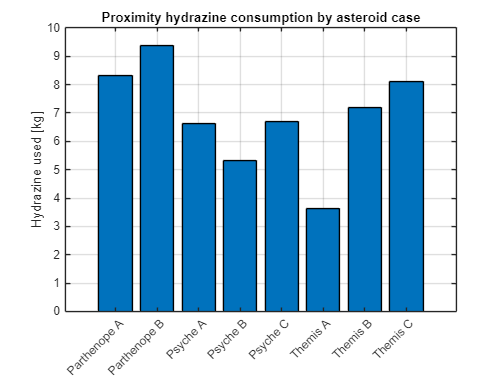


%% Section 7: Plot case-by-case hydrazine consumption

figure;
bar(Hyd_Total_kg);
xticks(1:n_cases);
xticklabels(Case);
xtickangle(45);
ylabel('Hydrazine used [kg]');
title('Proximity hydrazine consumption by asteroid case');
grid on;

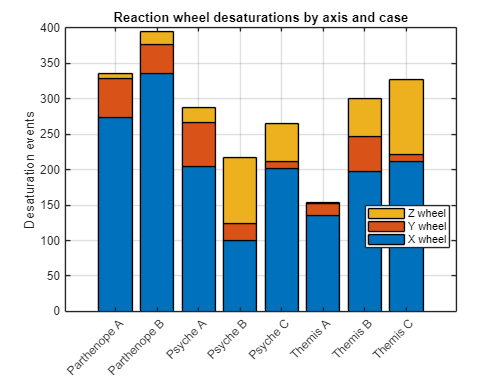


%% Section 8: Plot desaturation count by case

figure;
bar([X_Desats, Y_Desats, Z_Desats], 'stacked');
xticks(1:n_cases);
xticklabels(Case);
xtickangle(45);
ylabel('Desaturation events');
title('Reaction wheel desaturations by axis and case');
legend('X wheel','Y wheel','Z wheel','Location','best');
grid on;


%% Section 9: Save summary tables

writetable(case_results_table, 'asteroid_proximity_largest_rotation_summary.csv');
writetable(asteroid_totals_table, 'asteroid_proximity_totals_summary.csv');

fprintf('\nSaved summary tables:\n');


Saved summary tables:


fprintf('  asteroid_proximity_largest_rotation_summary.csv\n');

  asteroid_proximity_largest_rotation_summary.csv


fprintf('  asteroid_proximity_totals_summary.csv\n');

  asteroid_proximity_totals_summary.csv



%% Local function: run one proximity case

function result = run_proximity_case( ...
    case_file, ...
    case_name, ...
    asteroid_name, ...
    altitude_km, ...
    target_num_steps, ...
    theta_event_min, ...
    theta_event_min_deg, ...
    slew_rate, ...
    slew_rate_deg_s, ...
    I_body, ...
    RW_H_sat, ...
    RW_H_target, ...
    Isp, ...
    g0)

    data = load(case_file);

    Rsc = data.Rsc;
    n_axis_full = data.n_axis;
    theta_rot_full = data.theta_rot;

    original_num_steps = length(theta_rot_full);

    % Select the largest absolute rotation changes.
    [~, ranked_idx] = sort(abs(theta_rot_full), 'descend');

    n_keep = min(target_num_steps, original_num_steps);

    sample_idx = ranked_idx(1:n_keep);

    % Sort selected samples back into chronological order.
    sample_idx = sort(sample_idx);

    theta_rot = theta_rot_full(sample_idx);
    n_axis = n_axis_full(sample_idx,:);

    original_step_idx = sample_idx(:);

    N = length(theta_rot) + 1;

    % Validity mask over selected intervals.
    valid_step = true(N-1,1);

    for k = 1:N-1
        original_k = original_step_idx(k);

        Rk = get_Rsc_k(Rsc, original_k);
        Rk1 = get_Rsc_k(Rsc, original_k+1);

        if any(isnan(Rk),'all') || any(isnan(Rk1),'all')
            valid_step(k) = false;
        end
    end

    n_invalid = sum(~valid_step);

    theta_rot_deg = theta_rot(:);
    theta_total = zeros(N-1,1);

    for k = 1:N-1
        if ~valid_step(k)
            continue;
        end

        theta_total(k) = deg2rad(abs(theta_rot_deg(k)));
    end

    % Wheel states.
    H_RW = zeros(N,3);
    H_RW_mag = zeros(N,1);
    H_RW_x = zeros(N,1);
    H_RW_y = zeros(N,1);
    H_RW_z = zeros(N,1);

    sat_flag = zeros(N,1);
    sat_axis_flag = zeros(N,3);

    desat_count = 0;
    m_RCS_vec = [];
    desat_times = [];
    desat_axes = [];
    H_dump_vec = [];

    slew_time_s = zeros(N-1,1);
    slew_H_mag = zeros(N-1,1);
    slew_H_xyz = zeros(N-1,3);

    wheel_H_peak_xyz_Nms = zeros(N-1,3);
    wheel_H_after_xyz_Nms = zeros(N-1,3);

    for k = 1:N-1
        H_RW(k+1,:) = H_RW(k,:);

        if ~valid_step(k)
            H_RW_mag(k+1) = norm(H_RW(k+1,:));
            H_RW_x(k+1) = H_RW(k+1,1);
            H_RW_y(k+1) = H_RW(k+1,2);
            H_RW_z(k+1) = H_RW(k+1,3);
            continue;
        end

        if theta_total(k) > theta_event_min
            axis_k = n_axis(k,:);

            if any(isnan(axis_k)) || norm(axis_k) < 1e-12
                axis_k = [0 0 1];
            else
                axis_k = axis_k ./ norm(axis_k);
            end

            slew_time_s(k) = theta_total(k) / slew_rate;

            omega_k = slew_rate .* axis_k;

            H_slew = (I_body * omega_k')';

            slew_H_mag(k) = norm(H_slew);
            slew_H_xyz(k,:) = H_slew;

            H_RW(k+1,:) = H_RW(k+1,:) + H_slew;

            wheel_H_peak_xyz_Nms(k,:) = H_RW(k+1,:);

            for axis_id = 1:3
                H_axis = H_RW(k+1,axis_id);

                if abs(H_axis) >= RW_H_sat
                    sat_flag(k+1) = 1;
                    sat_axis_flag(k+1,axis_id) = 1;
                    desat_count = desat_count + 1;

                    H_pre_axis = H_axis;
                    H_post_axis = sign(H_pre_axis) * RW_H_target;

                    DeltaH_axis = H_pre_axis - H_post_axis;

                    m_k = abs(DeltaH_axis) / (Isp * g0);

                    m_RCS_vec(end+1,1) = m_k;
                    desat_times(end+1,1) = k+1;
                    desat_axes(end+1,1) = axis_id;
                    H_dump_vec(end+1,1) = abs(DeltaH_axis);

                    H_RW(k+1,axis_id) = H_post_axis;
                end
            end

            wheel_H_after_xyz_Nms(k,:) = H_RW(k+1,:);
        end

        H_RW_mag(k+1) = norm(H_RW(k+1,:));
        H_RW_x(k+1) = H_RW(k+1,1);
        H_RW_y(k+1) = H_RW(k+1,2);
        H_RW_z(k+1) = H_RW(k+1,3);
    end

    is_slew = theta_total > theta_event_min;
    event_idx = find(is_slew);
    event_count = length(event_idx);

    if event_count > 0
        Event_ID = (1:event_count)';
        Step = event_idx(:);
        Original_Step = original_step_idx(Step);
        Theta_rot_deg = abs(theta_rot_deg(Step));
        Slew_Time_s = slew_time_s(Step);
        Slew_Time_min = Slew_Time_s ./ 60;
        Slew_H_Nms = slew_H_mag(Step);
        Slew_H_X_Nms = slew_H_xyz(Step,1);
        Slew_H_Y_Nms = slew_H_xyz(Step,2);
        Slew_H_Z_Nms = slew_H_xyz(Step,3);
        Wheel_X_Peak_Nms = wheel_H_peak_xyz_Nms(Step,1);
        Wheel_Y_Peak_Nms = wheel_H_peak_xyz_Nms(Step,2);
        Wheel_Z_Peak_Nms = wheel_H_peak_xyz_Nms(Step,3);
        Wheel_X_After_Nms = wheel_H_after_xyz_Nms(Step,1);
        Wheel_Y_After_Nms = wheel_H_after_xyz_Nms(Step,2);
        Wheel_Z_After_Nms = wheel_H_after_xyz_Nms(Step,3);
        Desat_This_Step = logical(sat_flag(Step+1));
        Dumped_Momentum_Nms = zeros(event_count,1);
        Hydrazine_g = zeros(event_count,1);

        for j = 1:event_count
            mask = desat_times == (Step(j)+1);

            if any(mask)
                Dumped_Momentum_Nms(j) = sum(H_dump_vec(mask));
                Hydrazine_g(j) = sum(m_RCS_vec(mask)) * 1000;
            end
        end

        event_table = table( ...
            Event_ID, ...
            Step, ...
            Original_Step, ...
            Theta_rot_deg, ...
            Slew_Time_s, ...
            Slew_Time_min, ...
            Slew_H_Nms, ...
            Slew_H_X_Nms, ...
            Slew_H_Y_Nms, ...
            Slew_H_Z_Nms, ...
            Wheel_X_Peak_Nms, ...
            Wheel_Y_Peak_Nms, ...
            Wheel_Z_Peak_Nms, ...
            Wheel_X_After_Nms, ...
            Wheel_Y_After_Nms, ...
            Wheel_Z_After_Nms, ...
            Desat_This_Step, ...
            Dumped_Momentum_Nms, ...
            Hydrazine_g);
    else
        event_table = table();
    end

    if desat_count > 0
        Desat_ID = (1:desat_count)';
        Step = desat_times(:);
        Axis_ID = desat_axes(:);

        Axis_Name = strings(desat_count,1);
        Axis_Name(Axis_ID == 1) = "X";
        Axis_Name(Axis_ID == 2) = "Y";
        Axis_Name(Axis_ID == 3) = "Z";

        Dumped_Momentum_Nms = H_dump_vec(:);
        Hydrazine_g = m_RCS_vec(:) .* 1000;

        desat_table = table( ...
            Desat_ID, ...
            Step, ...
            Axis_ID, ...
            Axis_Name, ...
            Dumped_Momentum_Nms, ...
            Hydrazine_g);
    else
        desat_table = table();
    end

    if event_count > 0
        peak_x = max(abs(wheel_H_peak_xyz_Nms(:,1)));
        peak_y = max(abs(wheel_H_peak_xyz_Nms(:,2)));
        peak_z = max(abs(wheel_H_peak_xyz_Nms(:,3)));
    else
        peak_x = 0;
        peak_y = 0;
        peak_z = 0;
    end

    n_desat_x = sum(desat_axes == 1);
    n_desat_y = sum(desat_axes == 2);
    n_desat_z = sum(desat_axes == 3);

    hyd_x = sum(m_RCS_vec(desat_axes == 1));
    hyd_y = sum(m_RCS_vec(desat_axes == 2));
    hyd_z = sum(m_RCS_vec(desat_axes == 3));

    result.case_name = case_name;
    result.asteroid = asteroid_name;
    result.case_file = case_file;
    result.altitude_km = altitude_km;
    result.original_steps = original_num_steps;
    result.selected_steps = length(theta_rot);
    result.valid_intervals = sum(valid_step);
    result.invalid_intervals = n_invalid;
    result.min_selected_deg = min(abs(theta_rot_deg));
    result.max_selected_deg = max(abs(theta_rot_deg));
    result.slew_events = event_count;
    result.desat_events = desat_count;
    result.desat_x = n_desat_x;
    result.desat_y = n_desat_y;
    result.desat_z = n_desat_z;
    result.peak_x_Nms = peak_x;
    result.peak_y_Nms = peak_y;
    result.peak_z_Nms = peak_z;
    result.hyd_x_kg = hyd_x;
    result.hyd_y_kg = hyd_y;
    result.hyd_z_kg = hyd_z;
    result.hyd_total_kg = sum(m_RCS_vec);
    result.event_table = event_table;
    result.desat_table = desat_table;
end

%% Local helper function: get Rsc at index k

function Rk = get_Rsc_k(Rsc,k)
    dims = size(Rsc);

    if numel(dims) == 3 && dims(1) == 3 && dims(2) == 3
        Rk = Rsc(:,:,k);
    elseif numel(dims) == 3 && dims(2) == 3 && dims(3) == 3
        Rk = squeeze(Rsc(k,:,:));
    else
        error('Rsc must be either 3x3xN or Nx3x3.');
    end
end